# Thermodynamique & Histoire

Centrale Marseille mène l'enquête 

(*Pascal Denis — Juillet 2021)*	

Version 5.0

## Introduction		

Tout étudiant a entendu parler pendant ses études de la pression de vapeur saturante, et en particulier de l'équation d’Antoine. C’est sur la base de cette dernière que nous allons être amenés à utiliser MATLAB© pour effectuer une analyse numérique, scientifique, mathématique, thermodynamique, historique et typographique. 

Lorsque l’on souhaite connaître la pression de vapeur saturante d’un corps, il existe plusieurs solutions : 		

- Faire des mesures exprérimentales		

- Chercher dans les tables les données tabulées, si elles existent ;

- Utiliser une équation permettant de calculer la pression de vapeur saturante. 			

C’est là ou nous allons étudier les travaux de Charles Antoine (1825-1897). Des ouvrages recensent les valeurs des coefficients de cette équation [1] [2] pour de nombreux corps et le [WebBook NIST](https://webbook.nist.gov/cgi/cbook.cgi?ID=C7732185&Units=SI&Mask=4#Thermo-Phase) (cas de l'eau) regorge de coefficients d'antoine . Sa simplicité sur un large spectre de température en fait une candidate robuste pour bon nombre de calculs.		

Vous avez suivi les cours en ligne sur MATLAB Academy, pour maîtriser les bases de MATLAB : 

- MATLAB Onramp lors de l'installation en sptembre		

- Introduction to Symbolic Math with MATLAB

- Solving Nonlinear Equations with MATLAB

- Introduction to Statistical Methods with MATLAB

 Nous allons donc passer à la pratique

C'est parti !

**Remarque **: TOUTES les références  vous sont accessibles, soit sur le site de la Bibliothèque Nationale de France (BnF, Gallica), soit sur des liens éditeurs (Springer, Science directe)

## **Un peu de théorie **

Émile Clapeyron (1799-1864) va reprendre les travaux de Sadi Carnot (1796-1832)  [3] et publier ses résultats pour obtenir en particulier la relation qui porte son nom [4]  : 


$$\frac{\textrm{dP}}{\textrm{dT}}=\frac{H_{\textrm{vap}} -H_{\textrm{liq}} }{T\cdot \left(V_{\textrm{vap}} -V_{\textrm{liq}} \right)}\;\left(1\right)$$


En utilisant la loi des gaz parfaits et en considérant que l'enthalpie de changement d'état est constante, on obtient la relation dite de "Clausius - Clapeyron", permettant de prédire assez moyennement la pression de vapeur saturante d'un corps en fonction de sa température. En négligeant le volume massique liquide devant celui de la vapeur, et en appliquant la loi des gaz parfait, on obtient facilement : 


$$\frac{\textrm{dP}}{\textrm{dT}}=\frac{P\Delta H_{\textrm{vap}} }{{\textrm{RT}}^2 }\;\left(2\right)$$


Nous sommes en 1834, mais notre analyse symbolique est de 2020 !

## Analyse Symbolique simple ...

Première étape, calcul de la variance de l'équilibre liquide-vapeur : 

**Réponse** : Le calcul de la variance nous indique qu lors du changement d'état liquide-vapeur nous donne 1, dans ces conditions, la pression de saturation (noté P ici ) ne dépend plus que de T.

% Traduire en symbolique l'équation (2)
%
% commandes utiles : syms, diff 


% Définir les conditions initiales de notre équation différentielle : T0, P0
%
% Utiliser la variable cond pour affecter P0 à P(T0)



% Résoudre alors l'équation différentielle symboliquement
% une utlisation de dsolve pourrait être judicieux


% Affichage de l'expression  plus sympathique
% pretty ... mais pas Woman 



%% Pour les utilisateurs de LaTeX, l'expression est  fournie par : 
% Latex ...



% Transformation de l'expression symbolique en fonction MATLAB "online"
%




## Données de base et de référence 

### Soyons précis ...

— Constante des gaz parfaits  :  [CODATA 2019](https://physics.nist.gov/cgi-bin/cuu/Value?r)

 % Valeur recommandée CODATA 2019

— Pression atmosphérique (Pa)

% exprimée en [Pa]

— Température d'ébullition de l'eau à P = 1 atm

% exprimée en [K]

— Enthalpie de vaporisation à P = 1atm : [WebBook NIST - Thermophysical Properties of Water](https://webbook.nist.gov/cgi/fluid.cgi?ID=C7732185&Action=Page)

% Enthalpie du liquide saturé[kJ/mol]
% Enthalpie de la vapeur saturée[kJ/mol]

% Enthalpie de vaporisation[J/mol]

### Tracé la pression de vapeur saturante vs T, de -20°C à 120°C

% Tracé de la courbe obtenue

 % intervalle de température entre -20°C et 120 °C


% Amélioration du Tracé
% Ajouter des grilles, les labels pour les abscisses et les ordonnées,
% ainsi qu'un titre



% pour faire joli ...
% positionner le Point correspondant à la température normale de vaporisation.



## **Le besoin technique**

L’essor de la machine à vapeur, en France, va pousser les ingénieurs et scientifiques à améliorer les connaissances sur l’eau, et en particulier la vapeur. C’est donc dans ces conditions que Victor Regnault (1810-1878) va effectuer ses premières mesures des " Forces élastiques de la vapeur d’eau " [6] de −32 °C à 100 °C. Vous trouverez sur le site de la bibliothèque de France l' [Article de Regnault](http://gallica.bnf.fr/ark:/12148/bpt6k6568689c/f282.item.r=) et plus particulièrement [les mesures finalisées ](http://gallica.bnf.fr/ark:/12148/bpt6k6568689c/f343.item.r=)en 1844. Ce sont ces dernières que nous allons utiliser pour vérifier la relation de Clapeyron.

### Ajouts des données de Regnault

% Ajouter des données de Regnault sur la courbe précédente, prendra un
% nombre de point suffisant et judicieusement placé pour être représentatif
% Notez l'unité de pression utilisée



### Comparaison graphique 

En prenant les données de 0 à 100 °C, comparer graphiquement l'expérience et le modèle !

% Attention piège !
% Il faut changer les unités soit des données de Regnault, soit de la
% relation de Clapeyron, il est plus simple de changer la fonction en
% modifiant la valeur de P0.


### Comparaison graphique plus poussée

Victor Regnault va poursuivre ses mesures et aller de -32°C à 230 °C. Dans le fichier Pvap_Regnault_230.dat, vous avez à disposition toutes les mesures effectuées sur ce domaine de température. Seules les pressions sont fournies. Si vous souhaitez faire une comparaison avec des données au-delà de 230°C, vous pourrez les trouver dans le Perry Chemical Engineering's Handbook [11], ou bien dans le fichier de données Pvap_Perry.dat que nous avons préparé pour vous (T (K) , P(MPa)).

% Seules les pressions de vapeur sont fournies, 
% Lecture du fichier de données s'il est dans ce répertoire
% Effectuer le tracer et comparer avec la relation de Clapeyron



### Conclusion 

Comme vous  le constater à plus haute température, l'accord est de moins en moins bon. Le modèle de Clapeyron n'est donc plus adéquat. On pourra pousser la comparaison avec des données qui s'étaleraient jusqu'à la température critique, cela montrerait effectivment la relation de Clapeyron n'est plus fiable. 

## Allez Zou ! On utilise la base de données du Perry ! 

Afin de vérifier les données de Regnault, on va utiliser et comparer la pression de vapeur saturante de l'eau avec la formulation issue du Perry's Chemical Enginnerring Handbook [11, Table 2-8]

% Chargement de la base 
load Perry

% Récupération des données de l'eau 



Comme vous pouvez les constater, l'accord est parfait ou presque.

## L'article de Charles Antoine

Charles Antoine va proposer une nouvelle formulation de la tension de vapeur de l'eau dans les  [Comptes Rendus des Séances de l'Académie des Sciences](https://gallica.bnf.fr/ark:/12148/bpt6k30635/f684.item) et propose l'équation suivante (avec P en mm Hg et T en celsius). 


$$\log \;P=1,8843\left(4,7405-\frac{1000}{\theta }\right)\left(3\right)$$



$$\theta =230+T\;\left(4\right)$$


En utilisant les données précédentes, tracez la fonction proposée par Charles Antoine et comparer les données de Regnault proposées dans le fichier Pvap_Regnault_230.dat. Comparez les données de Regnault avec celles de Ch. Antoine. 

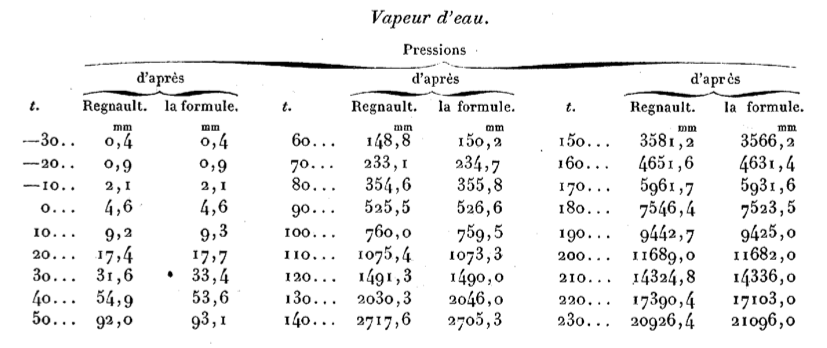

**Réponse** : légère perte de précision, mais a priori rien de grave. 

### Comparatif Antoine vs Regnault

En mathématique, le log désigne toujors le log népérien,  tracez donc cette fonction et comparez avec les points expérimentaux de Regnault (-32°C / 230°C). 

% Création d'une fonction inmine
% On peut a priori utiliser T comme variable de la fonction, cependant pour
% le fitting, il vaut mieux prendre x


% Tracer avec une ligne continue verte la relation d'Antoine et en rougeles données de Regnault.
% (utilisez l'option 'MarkerEdgeColor' ...
% 
% il faut bien mettre un peu de couleur !



% Ajout d'informations (noms des axes, titre, quadrillage)




**Votre remarque** : Il y a clairement un problème ...La courbe verte est confondue avec l'axe des x, le log utilisé par Ch. Antoine est peut-être décimal , vérifez cette hypothèse. 

### Passons en log décimal

En passant au log décimal, vérifier la cohérence ou non avec les données de Regnault.

% Création d'une seconde fonction avec un log décimal



% Tracé de cette nouvelle fonction en magenta



**Réponse** : Ce n'est pas cela non plus ! Mais que c'est-il passé ?  

## Analyse du problème rencontré

Il n'y a pas le choix : soit les données de Regnault sont fausses, soit l'équation de Ch. Antoine est fausse.  Dans la mesure ou l'on a une assez bonne corrélation entre les données de notre cher Victor Regnault et la relation de Clapeyron, il semble évident que l'équation d'Antoine proposée n'est pas correcte, et pourtant son article a été accepté et validé par l'académie des sciences, et des milliers d'ingénieurs et scientifiques continuent à l'utiliser ... Pourriez-vous proposer d'autres idées pour valider/invalider les points expérimentaux ? 

### Let'go fitting !

Nous avons des points expérimentaux, nous avons une formulation,  effectuons allors ce que l'on appelle du 'fitting' 

% Fonction pour le fitting 



% Points de départ pour la recherche des coefficients


u'en pensez-vous ?  Comment pourriez-vous quantifier les écarts aux coefficients de la realtion d'Antoine?

***Réponses**** : Les résultats obtenus sont assez proches des coefficients initiaux, avec des écarts variables. Nous allons donc calculer l'écart en % de chaque coefficient : *

### *Analyse des écarts*


% Le premier coefficient présente un écart plus important que les 2 autres de manière substancielle. Conservons les 2 derniers coefficients et ajustons par fitting le 1er.

**Réponse** : Le premier coefficient présente un écart plus important que les 2 autres de manière substancielle. Conservons les 2 derniers coefficients et ajustons par fitting le 1er.  

## On touche au but !

À partir de l'analyse précédente, proposer un nouveau fitting des données expérimentales

Que pensez vous du résultats ? 

### Tracé final

Reprenez le tracé des données avec la relation suivante, et faites une conculsion : 


$$\textrm{log}\;\textrm{P}\;\textrm{=}\;\textrm{1}\textrm{,6843}\left(\textrm{4,7405}\;\textrm{−}\frac{\textrm{1000}}{\theta }\right)\;\left(5\right)$$



% Axes, label & Cie


% Tracé de la fonction d'Antoine

### Conclusion

## Épilogue 

 Charles Antoine  publiera en 1891 [9] une version améliorée de son équation pour l'eau, avec la forme moderne (Eq. 6)  que nous lui connaissons désormais. 


$$\log \;P=A-\frac{B}{T+C}\;\,\left(6\right)$$


Et si vous proposiez la valeur des coefficients A,B,C  ? 

La pression sera exprimée en Torr et la température en Celcius ...

Comparer avec la littérature [WebBook NIST](https://webbook.nist.gov/cgi/cbook.cgi?ID=C7732185&Units=SI&Mask=4#Thermo-Phase) : 

% Mise en place des données
% Attention PRession en bar !



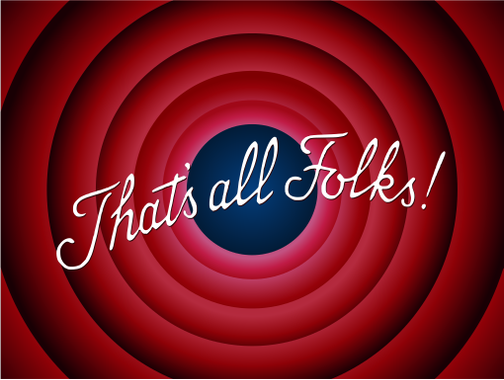

## Bibliographie		

[1] [Carl L Yaws. The Yaws Handbook of Vapor Pressure. Antoine coefficients. Gulf Professional Publishing, March 2015](https://www.sciencedirect.com/book/9780128029992/the-yaws-handbook-of-vapor-pressure). 						

[2] [J Dykyj, J Svoboda, R C Wilhoit, M Frenkel, and K R Hall. Vapor Pressure and Antoine Constants for Hydroncarbons, and Sulfur, Selenium, Tellurium, and Halogen Containing Organic Compounds. Springer, 1999 ](https://www.springer.com/gp/book/9783540647355)

[3] [Sadi Carnot. Réflexion sur la puissance motrice du feu et sur les machines propres à développer cette puissance. Chez Bachelier, Libraire, Paris, 1824](https://gallica.bnf.fr/ark:/12148/btv1b86266609/f10.double). 						

[4] [Émile Clapeyron. Mémoire sur la puissance motrice de la chaleur. Journal de l’École Royale Polytechnique, XIV(23) :153–191, 1834](https://gallica.bnf.fr/ark:/12148/bpt6k4336791). 						

[5] [J Bevan Ott and Juliana Boerio-Goates. Chemical Thermodynamics : Principles and Applications. Principles and Applications. Academic Press, June 2000](https://www.dawsonera.com/abstract/9780080500980). 						

[6] [Victor Regnault. Mémoire su rles forcese ́lastiquesde la vapeur d’eau.Annales de Chimie et de Physique, XI(3) :273–335, 1844](https://gallica.bnf.fr/ark:/12148/bpt6k6568689c/f282.image). 						

[7] [Ch Antoine. Calcul des tensions de diverses vapeurs. Comptes Rendus des Séances de lAcadémie des Sciences, 107 :778–780, 1888](http://visualiseur.bnf.fr/CadresFenetre?O=NUMM-3063&M=tdm). 						

[8] [Ch Antoine. Tensions de diverses vapeurs. Comptes Rendus des Séances de lAcadémie des Sciences, 107 :836–837, 1888](http://visualiseur.bnf.fr/CadresFenetre?O=NUMM-3063&M=tdm). 						

[9] [Ch Antoine. Tensions des vapeur. Annales de Chimie et de Physique, XXII(6) :281–288, 1891](https://gallica.bnf.fr/ark:/12148/bpt6k65674456/f287.image). 						

[10] [Ch Antoine. Tensions de vapeur : nouvelle relation entre les tensions et les températures. Comptes Rendus des Séances de lAcadémie des Sciences, 107 :681– 684, 1888](http://visualiseur.bnf.fr/CadresFenetre?O=NUMM-3063&M=tdm). 						

[11] [Robert H Perry and Don W Green. Perry’s chemical engineer’s handbook; 8th ed. McGraw-Hill chemical engineering series. McGraw-Hill, New York, NY, 2008](https://www.dawsonera.com/abstract/9780071593137). 						

[12] [Victor Regnault. Relation des expériences entreprises par ordre de Monsieur le ministre des travaux publics, et sur la proposition de la commission centrale des machines à vapeur, pour déterminer les principales lois et les données numériques qui entreront dans le calcul des machines à vapeur. Mémoires de l'Académie Royale des Sciences de l'Institut de France, XXI, 1847](https://fr.wikisource.org/wiki/Page:Mémoires_de_l’Académie_des_sciences,_Tome_21.djvu/37). 						